% for case 1: lambda*P_loss*A(1) + A(2)R + A(3)*R*R
hold on
A = [0.75,10,0.15]

A =     0.7500   10.0000    0.1500


cost_wr = A(1)*lambda(1)*P_loss_wr + A(2)*k_vector + A(3)*k_vector.*k_vector;
plot(k_vector,cost_wr,"LineWidth",2,"Color",'r','DisplayName',"Web-request")
% case 2 : lambda*P_loss*B(1) + B(2)R + B(3)*R*R
B = [0.65,10,0.3]

B =     0.6500   10.0000    0.3000


cost_cr = B(1)*lambda(2)*P_loss_cr + B(2)*k_vector + B(3)*k_vector.*k_vector;
plot(k_vector,cost_cr,"LineWidth",2,"Color",'g','DisplayName',"computing-request")
% case 3 : lambda*P_loss*C(1) + C(2)R + C(3)*R*R
C = [1,9,0.15]

C =     1.0000    9.0000    0.1500


cost_sr = C(1)*lambda(3)*P_loss_sr + C(2)*k_vector + C(3)*k_vector.*k_vector;
plot(k_vector,cost_sr,"LineWidth",2,"Color",'b','DisplayName',"storage-request")
% case 4 : lambda*P_loss*D(1) + D(2)R + D(3)*R*R
D = [2,10,0.3]

D =     2.0000   10.0000    0.3000


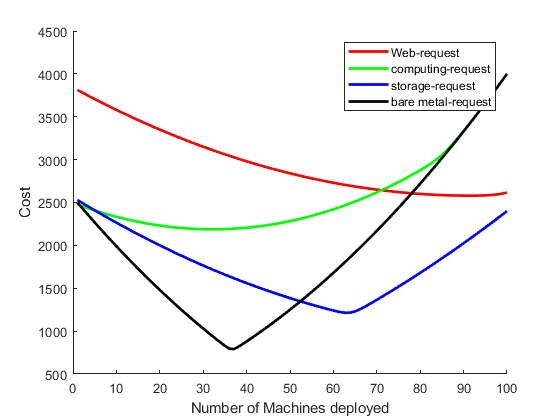

cost_bm = D(1)*lambda(4)*P_loss_bm + D(2)*k_vector + D(3)*k_vector.*k_vector;
plot(k_vector,cost_bm,"LineWidth",2,"Color",'k','DisplayName',"bare metal-request")
xlabel("Number of Machines deployed")
ylabel("Cost")
legend

I = [];
[M(1),I(1)] = min(cost_wr);
ans(1) = k_vector(I(1));
losses(1) = P_loss_wr(I(1))

losses = 0.1114

[M(2),I(2)] = min(cost_cr);
ans(2) = k_vector(I(2));
losses(2) = P_loss_cr(I(1))

losses =     0.1114    0.0006


[M(3),I(3)] = min(cost_sr);
ans(3) = k_vector(I(3));
losses(3) = P_loss_sr(I(1))

losses =     0.1114    0.0006    0.0000


[M(4),I(4)] = min(cost_bm);
ans(4) = k_vector(I(4));
losses(4) = P_loss_bm(I(1))

losses =     0.1114    0.0006    0.0000    0.0000


ans

ans =     91    32    63    37


total_cost = sum(M)

total_cost = 6.7706e+03